# 20.320 Project 1

Hello, this is a Live Function file. I like it because then it'll keep all the printed plots show up on the right side. Also, you're able to type out text like this instead of having everything commented—so I think it looks pretty :^ )

Go ahead and press **Run.**

## Standard RTK EGFR Model 

## Parameters

Here are all our parameters with units specified in the comments.

    % Find Rs_0 from a paper
    Kf = 3*10^7; %units?           from v1
    Kr = 3.8*10^-3; %units?        from v1
    Vs = 2.7/(6.022E23)/(4/3*3.14*(15E-6)^3); %receptors/second ==> Molar/sec/cell   from v13
    Ker = 5*10^-5; %units?         from v6
    Krec_r = 5*10^-3; %units?      from v6
    Kdeg_r = 6.67*10^-4; %units?   from v60
    Kdeg_d = 6.67*10^-4; %units?   from v62
    Ked = 5*10^-5; %units?         from v7
    Kcat = 1; %units?              from v3
    %there is also a constant for PDs --> Ds
    Kf_d = 1*10^7; %units?         from v2
    Kr_d = 0.1; %units?            from v2
    Kf_g = 1*10^7; % M (Are units correct, shouldnt kf be l/(mol*s)
    Kr_g = 0.055*10^7;% M (30 - 713 nM, we could try adjusting this)

## ODEs

Here are out ODE with all the constants vecorized :^ )

    options = odeset('AbsTol', 1e-12, 'RelTol', 1e-12);
    y0 = [1E-10, 5E5/(6.022E23)/(4/3*3.14*(15E-6)^3), 0, 0, 0, 0, 0, 2E-6, 0]; % Initial conditions
    k = [Kf, Kr, Vs, Ker, Krec_r, Kdeg_r, Kdeg_d...
    Ked, Kcat, Kf_d, Kr_d, Kf_g, Kr_g]';

    tspan = logspace(0, 10);
    [t,y] = ode15s(@StandardSystem, tspan, y0, options, k);

## Scripts and Figures

Scripts to plot and make things look pretty.

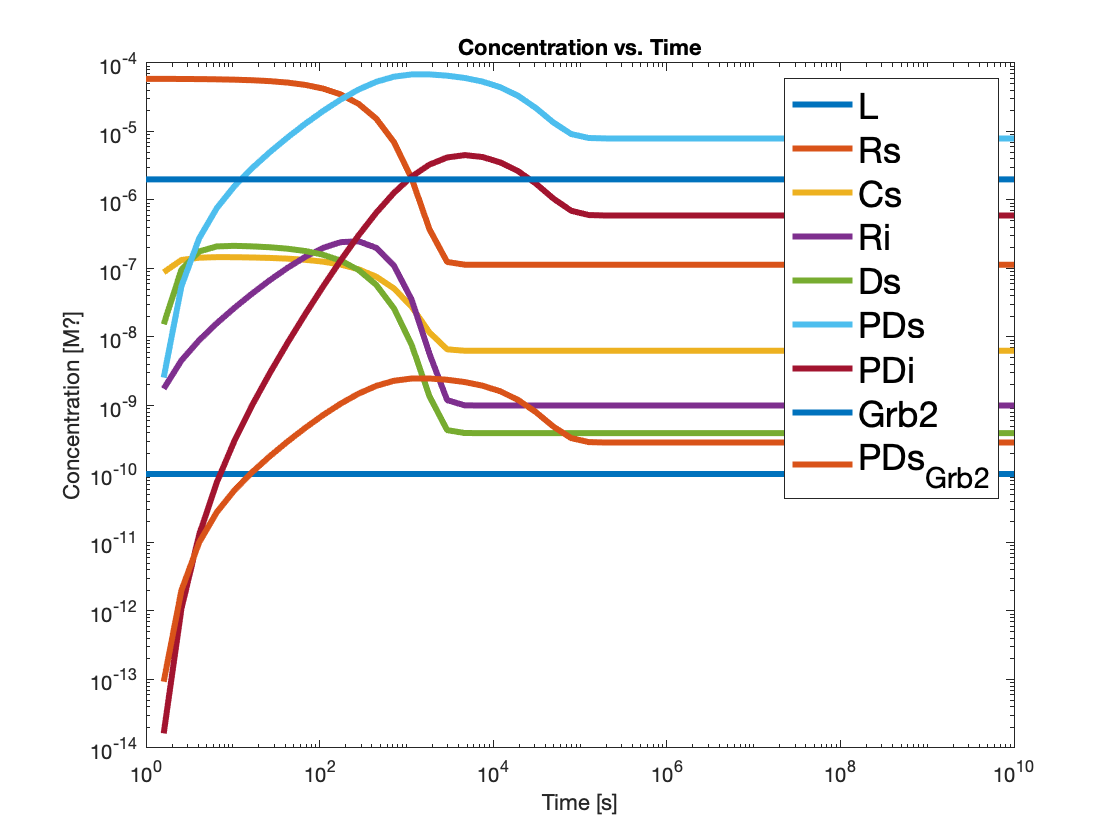

close all
% loglog(t, y(:, 2));
% hold on
% loglog(t, y(:, 3));
% loglog(t, y(:, 4));
loglog(t, y, 'LineWidth', 3);
title('Concentration vs. Time');
xlabel('Time [s]');
ylabel('Concentration [M?]');
lgd = legend('L', 'Rs', 'Cs', 'Ri', 'Ds', 'PDs', 'PDi', 'Grb2', 'PDs_{Grb2}');
lgd.FontSize = 18;

## Aberrant RTK EGFR Model

## Parameters

    % Find Rs_0 from a paper
    Kf = 3*10^7; %units?           from v1
    Kr = 3.8*10^-3; %units?        from v1
    Vs = 2.7/(6.022E23)/(4/3*3.14*(15E-6)^3); %receptors/second ==> Molar/sec/cell   from v13
    Ker = 5*10^-5; %units?         from v6
    Krec_r = 5*10^-3; %units?      from v6
    Kdeg_r = 6.67*10^-4; %units?   from v60
    Kdeg_d = 6.67*10^-4; %units?   from v62
    Ked = 5*10^-5; %units?         from v7
    Kcat = 1; %units?              from v3
    %there is also a constant for PDs --> Ds
    Kf_d = 1*10^7; %units?         from v2
    Kr_d = 0.1; %units?            from v2
    Kf_g = 1*10^7; % M (Are units correct, shouldnt kf be l/(mol*s)
    Kr_g = 0.055*10^7;% M (30 - 713 nM, we could try adjusting this)
    Kemr = 5*10^-5;    
    Krec_mR = 5*10^-3; 
    Kcat_m = 0.1; 
    Krec_rg = 5*10^-3; %make MUCH smaller than normal
    Kerg = 5*10^-8; %make MUCH smaller than normal
    Kdeg_mR = 6.67*10^-4;   
    Kdeg_erg = 6.67*10^-8; %make MUCH smaller than normal

## ODEs

Here are out ODE with all the constants vecorized :^ )

    options = odeset('AbsTol', 1e-12, 'RelTol', 1e-12);
    y_ab = [0, 2E-6, 5E5/(6.022E23)/(4/3*3.14*(15E-6)^3), 0, 0, 0, 0]; % Initial conditions
    k = [Kf, Kr, Vs, Ker, Krec_r, Kdeg_r, Kdeg_d...
    Ked, Kcat, Kf_d, Kr_d, Kf_g, Kr_g, Kemr, Krec_mR, Kcat_m, Krec_rg, Kerg, Kdeg_mR, Kdeg_erg]';

    tspan = logspace(0, 4);
    [t,y] = ode15s(@AberrantSystem, tspan, y_ab, options, k);

## Scripts and Figures

Scripts to plot and make things look pretty.

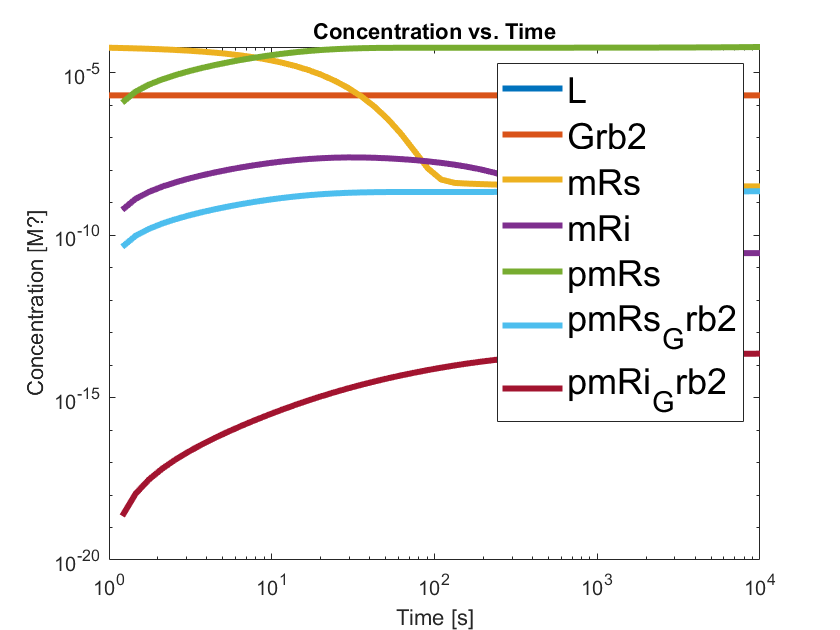

close all
% loglog(t, y(:, 2));
% hold on
% loglog(t, y(:, 3));
% loglog(t, y(:, 4));
loglog(t, y, 'LineWidth', 3);
title('Concentration vs. Time');
xlabel('Time [s]');
ylabel('Concentration [M?]');
lgd = legend('L','Grb2','mRs','mRi','pmRs','pmRs_Grb2','pmRi_Grb2');
lgd.FontSize = 18;

## Functions

We can either decide to have all our functions here at the bottom of the file. Or we can have them as separate .m files in the main folder (such as ExampleFunction.m).

% 